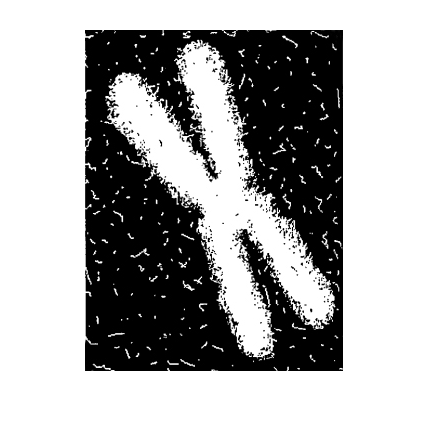

I = imread('NST.jpg');
figure;imshow(I)

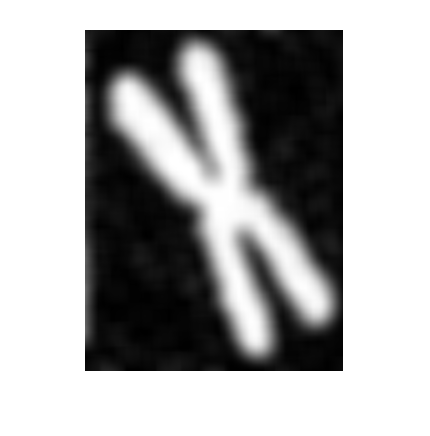


h=fspecial('gaussian',25,10); %tạo kernel lọc gaussian,sigma=10
g=imfilter(I,h,'replicate'); %áp bộ lọc lên ảnh, replicate: vùng viền ảnh thêm vào các pixels giống pixels ảnh gần nhất khi kernel trượt qua
figure;imshow(g)

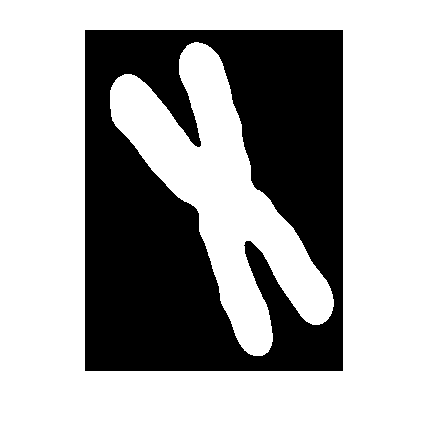


g1=im2bw(g,graythresh(g)); %tách vùng bằng ngưỡng tự động Otsu
figure;imshow(g1)

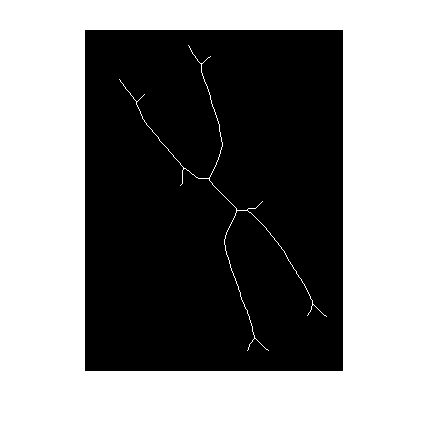


s=bwmorph(g1,'skel',Inf); %tìm khung sườn cho vùng, inf = co lại vùng khi cho đến khi khung sườn chỉ là những điểm
figure;imshow(s)

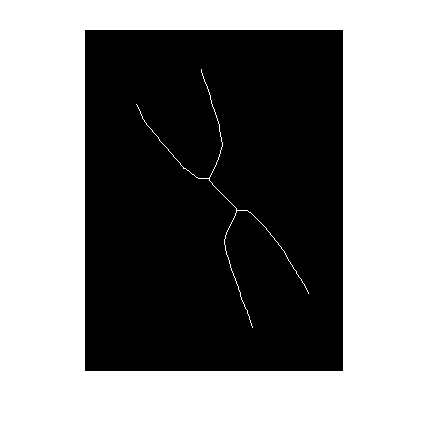


s=bwmorph(s,'spur',25);%bỏ đi các nhánh dư nhỏ 25 lần; 25=(sigma/2)^2
figure;imshow(s)